# Short Project 2 (Robot Móvil)

Yimin Pan, Adnan Akortal

clear;
clc;
clear poseIntegration % clear persistent variables
clear poseIntegration2 
load('Work_Space_Localization_Short_project.mat');

Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]';% The Robot icon is a triangle
Lsum = data_enc(:,6)/1000;
Rsum = data_enc(:,7)/1000;
IC = [0 0 pi/2]; %[xo,yo,th0]
V = diag([0.01^2 0.01^2]); % noise
Pk0 = pk.signals.values(:,:,1);
S = width/2/1000; % mm to m
error = [0 0 0];
errors(1,:) = error;
number_landmarks = zeros(1,523);
landmark1 = zeros(1,523);
landmark2 = zeros(1,523);
landmark3 = zeros(1,523);
landmark4 = zeros(1,523);
detPK = zeros(1,523);

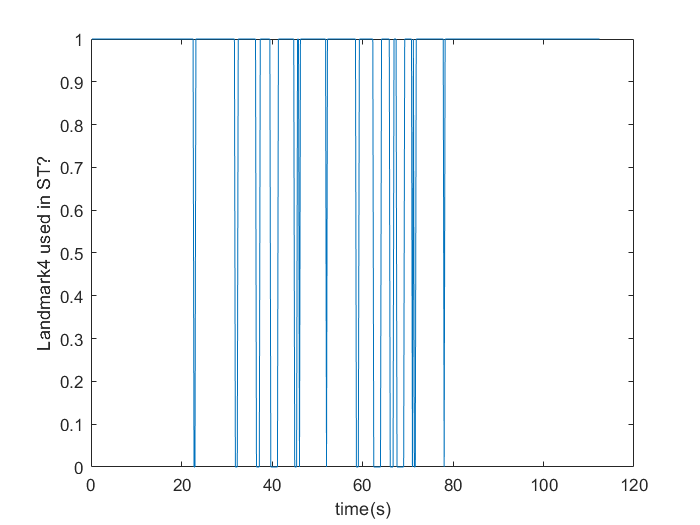

for index=1:523
    
    % The given script
    t = 0: 2*pi/359 : 2*pi;
    P = polar(t, 4.5 * ones(size(t)));% to fix the limits
    set(P, 'Visible', 'off')
    subplot(2,2,1)
    polar(t, lds_dis (index,2:361), '--g'); % Ploting the laser data wrt Robot frame
    title ('Laser data at Robot Reference Frame','FontWeight','bold','FontSize',8)  
    subplot(2,2,2)
    title ('Data on Wordl Reference Frame', 'FontWeight','bold','FontSize',8)
    axis([-3 3 -2 4])
    grid on
    hold on
    for i=1:4 % plotting the 4 Land Marks
        circle (LandMark(i,:)',0.15)
    end
    scatter(ldx(index,:), ldy(index,:)) % plotting the land mark seen by the Robot wrt  wordl reference frame
    plot (trajec(:,1), trajec(:,2), 'r.','LineWidth',1.5) % Plotting the trajectory
    Robot_tr=transl(trajec(index,1),trajec(index,2),0)*trotz(mod(trajec(index,3)+pi/2,2*pi))*Robot;% moving the robot 
    patch(Robot_tr(1,:), Robot_tr(2,:),'b');
    plot_ellipse(pk.signals.values(1:2,1:2,index),[trajec(index,1), trajec(index,2)],'g'); % Plotting the covariance matrix
    
    
    % ----------------------------------------------------------------
    
    % Plot pose integration without error feedback
    subplot(2,2,4)
    title ('Robot Pose Integration without error', 'FontWeight','bold','FontSize',8)
    axis([-3 3 -2 4])
    grid on
    hold on
    plot(trajec(:,1), trajec(:,2), 'r.','LineWidth',1.5)
    % calculate pose with noise
    if index == 1
        [poseT, poseEst, Pk] = poseIntegration(V, Pk0, IC, Lsum(1), Rsum(1), S);
    else 
         L = Lsum(index)-Lsum(index-1);
         R = Rsum(index)-Rsum(index-1);
        [poseT, poseEst, Pk] = poseIntegration(V, Pk0, IC, L, R, S);
    end 
    % Move robot to that pose
    x = poseEst(1); y = poseEst(2); theta = poseEst(3);
    detPK(index) = sqrt(det(Pk));
    Robot_T = transl(x, y, 0)*trotz(theta)*Robot;
    patch(Robot_T(1,:), Robot_T(2,:),'b');
    plot_ellipse(Pk(1:2, 1:2),[x, y],'g'); 
    
    % Landmark in Robot Reference Frame (pink colour)
    posV = polar2Cart(lds_dis(index,:));
    scatter(posV(:,1), posV(:,2), [], [255,192,203]/255);  
    
    scatter(LandMark(:,1), LandMark(:,2), [], [0,0,0]/255);  % True Landmark (black)
    
    laserW = rob2W(posV, poseEst);
    %scatter(laserW(:,1), laserW(:,2), 'cyan') % no need to plot twice
    
    % we plot the landmark in world reference frame each one associated to
    % the nearest true landmark by colour
    asLandM = assoLndMrk(LandMark, laserW); 
    aux = unique(asLandM);
    number_landmarks(index) = size(aux,2);
    landmark1(index) = ismember(1,aux);
    landmark2(index) = ismember(2,aux);
    landmark3(index) = ismember(3,aux);
    landmark4(index) = ismember(4,aux);
    scatter(laserW(:,1), laserW(:,2), [] ,asLandM); % Landmark in World Reference Frame 
    
    % -------------------------------------------------------------
    % bacically the same
    
    % pose integration calculating the error and correcting the pose in the
    % next iteration
    subplot(2,2,3);
    title ('Robot Pose Integration with error feedback', 'FontWeight','bold','FontSize',8)
    axis([-3 3 -2 4])
    grid on
    hold on
    plot(trajec(:,1), trajec(:,2), 'r.','LineWidth',1.5)
    if index == 1
        [poseT, poseEst, Pk] = poseIntegration2(V, Pk0, IC, Lsum(1), Rsum(1), S, error);
    else 
        [poseT, poseEst, Pk] = poseIntegration2(V, Pk0, IC, L, R, S, error);
    end 
    x = poseEst(1); y = poseEst(2); theta = poseEst(3);
    Robot_T = transl(x, y, 0)*trotz(theta)*Robot;
    patch(Robot_T(1,:), Robot_T(2,:),'b');
    if (~isnan(Pk(1,1)))
        plot_ellipse(Pk(1:2, 1:2),[x, y],'g'); 
    end
    posV = polar2Cart(lds_dis(index,:));
    scatter(posV(:,1), posV(:,2), [], [255,192,203]/255);  % Landmark in Robot Reference Frame (pink)
    scatter(LandMark(:,1), LandMark(:,2), [], [0,0,0]/255);  % True Landmark
    laserW = rob2W(posV, poseEst);
    asLandM = assoLndMrk(LandMark, laserW); 
    scatter(laserW(:,1), laserW(:,2), [] ,asLandM); % Landmark in World Reference Frame 
    error = ST(LandMark, asLandM, laserW);
    if index < 523
        errors(index+1,:) = error;
    end
    
    pause(0.01);
    clf
end

#### Plot square root determinant of Pk

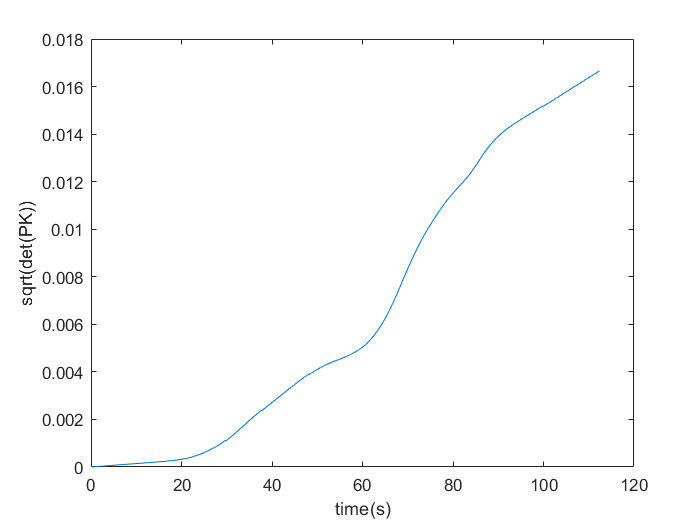

plot(data_enc(:,1), detPK);
xlabel("time(s)");
ylabel("sqrt(det(PK))");

#### X error over time

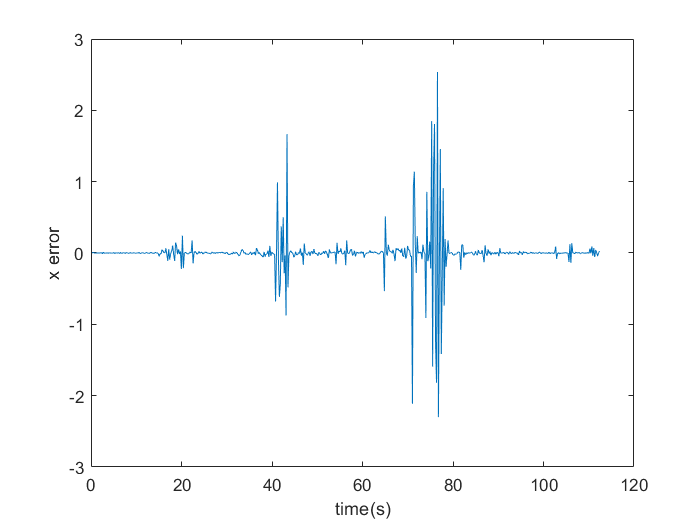

plot(data_enc(:,1)', errors(:,1));
xlabel("time(s)");
ylabel("x error");

#### Y error over time

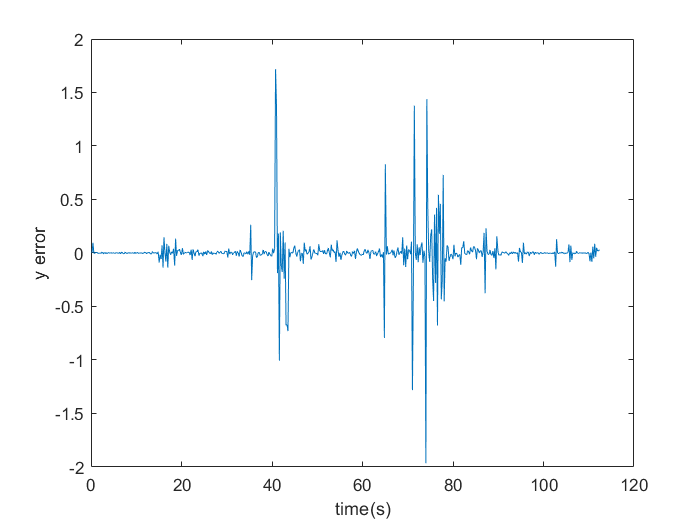

plot(data_enc(:,1)', errors(:,2));
xlabel("time(s)");
ylabel("y error");

#### Theta error over time

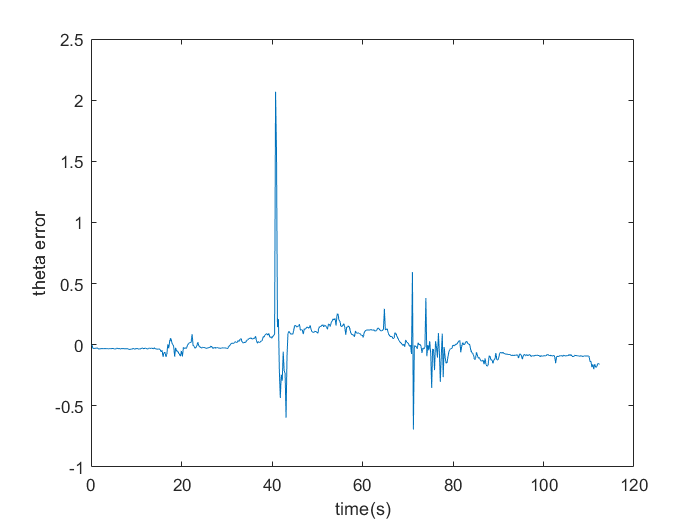

plot(data_enc(:,1)', errors(:,3));
xlabel("time(s)");
ylabel("theta error");

#### Number of landmarks used over time

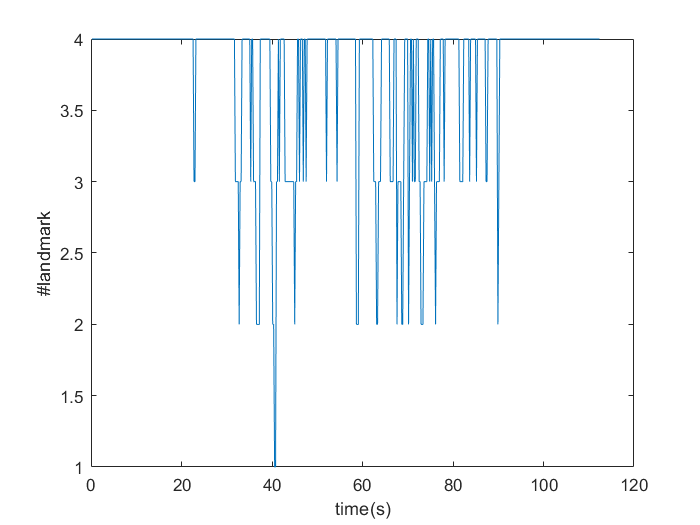

plot(data_enc(:,1)',number_landmarks);
xlabel("time(s)");
ylabel("#landmark");

#### Landmark 1 usage over time

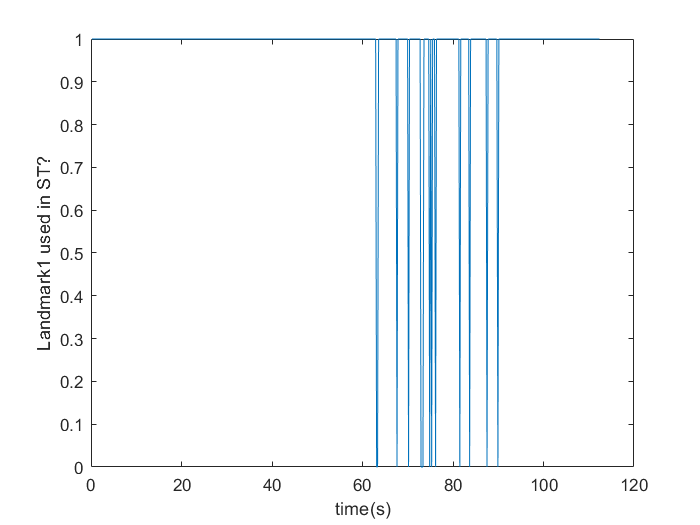

plot(data_enc(:,1)',landmark1);
xlabel("time(s)");
ylabel("Landmark1 used in ST?");

#### Landmark 2 usage over time

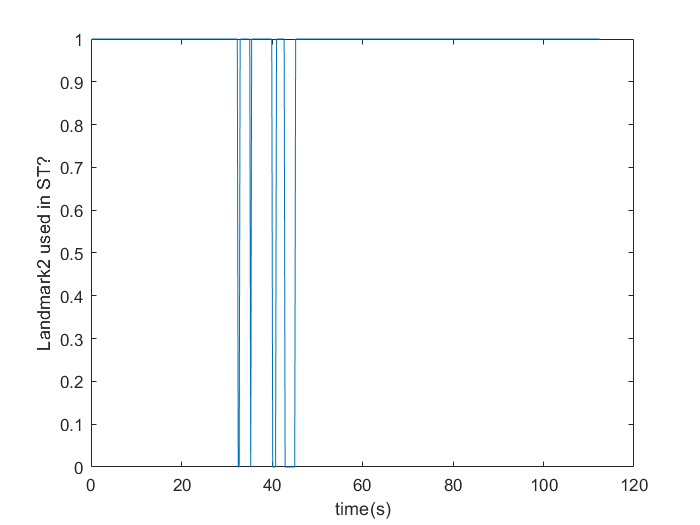

plot(data_enc(:,1)',landmark2);
xlabel("time(s)");
ylabel("Landmark2 used in ST?");

#### Landmark 3 usage over time

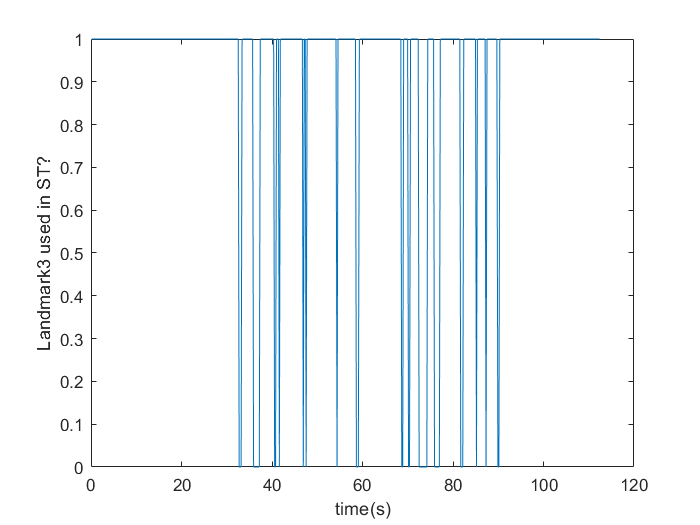

plot(data_enc(:,1)',landmark3);
xlabel("time(s)");
ylabel("Landmark3 used in ST?");

#### Landmark 4 usage over time

plot(data_enc(:,1)',landmark4);
xlabel("time(s)");
ylabel("Landmark4 used in ST?");